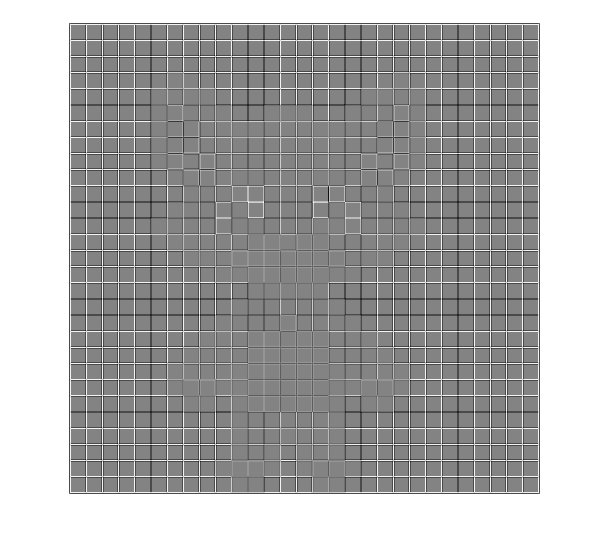

im = im2double(imread("pixel.png"))/255; %исходный массив 
yadro = [-1 -1 -1;-1 8 -1; -1 -1 -1];
ans1 = svert(im,yadro);
ans1 = (ans1-min(ans1(:)))/(max(ans1(:))-min(ans1(:))); % нормировка
imshow(ans1)


% imwrite(im,'C:\LATEX\Fourier_analiz\Fourier_6\4_0.png');
imwrite(ans1,'C:\LATEX\Fourier_analiz\Fourier_6\4_four.png');

function y = svert(im,m) %передается ядро
    h = height(im); w = width(im); %высота и ширина исходного
    f_im = fftshift(fft2(im, h+height(m)-1,w+width(m)-1)); %образ Фурье для изображения
    f_m = fftshift(fft2(m, h+height(m)-1,w+width(m)-1)); %образ для ядра
    d = f_im.*f_m;
    y = ifft2(ifftshift(d));
end